## 创建简单的深度学习网络用于分类

这是自己看和练习的版本。如果需要发给教授，那就另存为新文件。然后把中文翻译成英文，删掉不必要的注释和学习时产生的无用的代码。

加载数据

digitDatasetPath = '/home/wang/Downloads/digit/DigitDataset';
imds = imageDatastore(digitDatasetPath,'IncludeSubfolders',true,"LabelSource","foldernames");

%digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos','nndatasets','DigitDataset');
%上面是在matlab根目录中自带的数字集数据，让人学习用的。所以新手可以先不去下载原始的Mnist，那个对新手有点困难

浏览部分图像

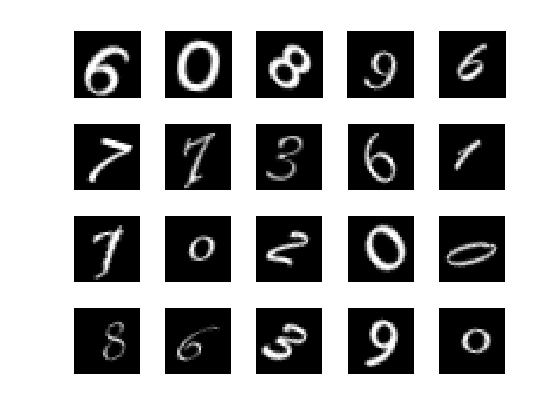

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

计算每个类别中有多少图像

labelCount = countEachLabel(imds)

labelCount = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


检查图像大小，因为要设定输入层的大小

img = readimage(imds,1);
size(img)

ans =     28    28


划分训练集和验证集

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomized');

定义网络架构

layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

设置训练选项

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

训练网络

net = trainNetwork(imdsTrain,layers,options);

预测和分析结果

YPred = classify(net,imdsValidation);
accuracy = sum(YPred == imdsValidation)/numel(imdsValidation.Labels)

Error using  ==  (line 30)
Invalid types for comparison.

98.52%的准确度